# Geoscience Data Analysis: Exercises

Student Name:

addpath ../codes
addpath ../data

clear all;

Most of the answers to the review questions can be simply found in the text.  Do not just copy and paste the answer, but rephrase into your own words.  Exercises are more involved generally requiring some programming.

## 1. Matlab

- Load the file Renland_annualized_d18O_data.xlsx.  You will need to load the sheet named *Renland stack*. Because it is not the first sheet, it will not load by default.  You will need to include the sheet as an option.  Use *help readtable()* to see how to add options.

- Write a function to produce a moving average with an arbitrary window size, $w$.  A moving average will take the first $w$ samples and average them and save the value in the first position of our series average vector.  Then shift $w$ by one position and repeat until the end of the window reaches the end of the record.

- Produce a moving average of the annual $\delta^{18}\text{O}$ using a decadal window.

- Plot both the original record and the moving average.

## 2. Distributions and Basic Statistics

### Review

        1.    What is the difference between a normal and a log-normal distribution?  How are they related?

        2.    How are the probability density function, cumulative distribution function, and quantile function related?

        3.    When working with data that must be counted, what probability density function are you likely to use?

        4.    What two common functions are used for producing random numbers?

        5.    How does rejection sampling produce a sample set with an arbitrary distribution?

        6.    As you collect data, what is the marginal improvement in the uncertainty in the mean as a function of the number of data collected?  Make a plot to illustrate the improvement.

        7.    Given a $y = f(x)$ and an uncertainty in $x$, how is the uncertainty in $y$ determined (in words)?

        8.    Why should you examine a histogram of the data and not simply an average?

        9.    How do histograms and kernel density estimates present the same information differently?

### Exercises

        2.1    In this set of exersizes, you will load a dataset, determine the nature of the data distribution and describe its characteristics, and produce a synthetic dataset with similar properties.

            Load the file *granite_hp_age.xlsx* using the readtable command.

            Create a histogram of the data field *heat_production*. It may take some trial and error to produce a reasonable plot.  Use 'help histogram' to learn about the options.  Make sure you label your axes.

            What type of distribution best describes the data?

            Compute the relevant moments for the data.

            Produce an ideal distribution based on the scale parameters.

            Produce a synthetic dataset using the same characteristics as the original dataset.

            2.2    Find three distinctly different equations in your field of research.  Identify the independent variables and propagate the errors for the dependent variable.  Typeset the equations and the equation for the estimated uncertainty below.  The live script uses latex to typeset equations.  To start and end an equation, use a dollar ($) sign.  Once you start the equation, you can double click on it to enter an editor mode.


$$\sigma_y = \left(\frac{\sum_i^N \sigma_{x_i}^2}{N}\right)^{1/2}$$


## 3. Hypothesis Testing and Regression

### Review

        1.    Describe the general process of hypothesis testing.

        2.    A p-value *is not *the probability of rejecting a null hypothesis in error, so what is it?

        3.    Although Pearson correlation coefficients are the most commonly used method to compute a correlation coefficient, what are its drawbacks and what can be done to obtain less biased result?

        4.    Why do we need more than one hypothesis testing method, e.g. Student's $t$-test and $F$-test?

        5.    Can qualitative data be used for hypothesis testing?  If so, what methods can be used?

        6.    What is an outlier and why is their no consensus as to what constitutes an outlier?

        7.    Do all outliers bias models of multiple variables?  How can we assess their influence?

        8.    What are the two conditions that must be met for a function to be linear?

        9.    Is it better to linearize a non-linear function before developing a regression model?  Why or why not?

        10.    What are the three challenges with producing inversion models?  How can they be mitigated?

### Exercises

In this set of exercizes, you will characterize the relationship between two or more datasets.

        3.1    Produce a Q–Q plot for the granite heat production dataset.

        3.2    Extract the heat production data just for Australia using *inpolygon.m* and the latitude and longitudes associated with the data to determine whether Australian heat production accepts or rejects the null hypothesis for a $t$-test against the global mean.

        3.3    In table *rock_prop.xlsx* you are given estimates for the physical properties of a number of rock types.  Compute the correlation coefficients between each property using the Pearson, Spearman and Kendall methods.  You should end up with a matrix of correlations where each column represents one of the columns in the table and each row represents the same columns in the same order.

         3.4    Use the physical properties table from above for this problem

            a.    Develop a linear relationship between density and p-wave velocity.  Make a plot showing your result and compute the relevant statistics, RMS misfit, $r^2$, and confidence intervals.

            b.    Perform a leverage analysis and outlier analysis.  Which points should you be concerned about?

            c.    Remove the outliers from above and recompute the linear model as in (a).  How did your result change?

## 4. Multivariate and Geochemical Data

### Review

        1.    Imagine situations when you will use plots that display >2-dimensional data in your thesis or field of study.  What type of data would you plot and what type of plot would you choose?  Consider a scatter plot, heat map and contour/surface plot?  Would you choose a radar plot for anything?

        2.    What is the advantage of using techinques such as PCA and MDS to investigate multivariate datasets? 

        3.    How does concentration data differ from many other types of data?

        4.    What is the purpose of log-centering compositional data?

        5.    What is the advantage of the isometric-log ratio transform over the other types?

        6.    What order simplex is plotted on a ternary diagram?

### Exercises

In this set of exercizes, you will explore some of the complications that arise with geochemical data and use dimensional reduction techniques to simplify the interpretation of multidimensional data.

        4.1    Perform PCA using a sedimentary rock types.  Use the function *rockgroup.m* to select sedimentary and igneous data separately from *rock_geochem.xlsx*.  How do they differ from igneous rocks?

        4.2    Perform classical MDS using a sedimentary rock types than is shown in the notes.

        4.3    Perform a classical MDS using only granites but separate them into bins of different ages.  Is their a discernable difference between old and new granites?  Is there a trend with age?

data = readtable('rock_geochem.xlsx');


oxides = {'sio2','tio2','al2o3','feo_tot','mgo','cao','na2o','k2o','p2o5'};

age_bins = [0:200:4000];
for i = 1:length(age_bins)-1
    ind = age_bins(i) <= data.avg_age & data.avg_age < age_bins(i+1);
    bin_name{i} = [num2str(age_bins(i)),' to ',num2str(age_bins(i+1))];
    
    data.agebin(ind) = {bin_name{i}};
end

indg = strcmp(data.rock_type,'granite');
R = radarprep(data(indg,:),'agebin',bin_name,oxides);

for i = 1:length(R.types)
    for j = 1:length(R.types)
        D(i,j) = sqrt(sum((R.vals(i,:) - R.vals(j,:)).^2));
    end
end

% find a configuration with those inter-point distances
[Y eigenvals] = cmdscale(D);

Dtriu = D(find(tril(ones(length(R.types)),-1)))';
maxrelerr = max(abs(Dtriu-pdist(Y(:,1:2))))./max(Dtriu)

maxrelerr = 0.1478

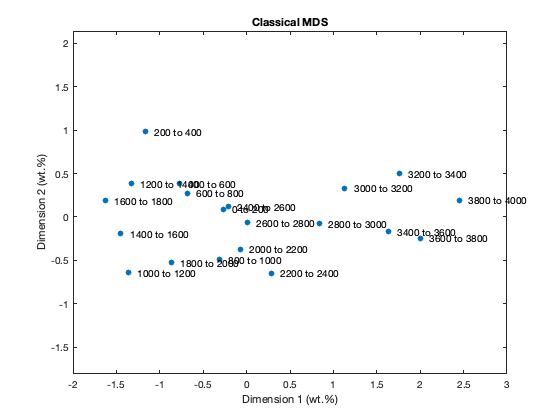

figure;
scatter(Y(:,1),Y(:,2),'o','filled')
text(Y(:,1)+0.1,Y(:,2),R.types)

xlabel('Dimension 1 (wt.%)');
ylabel('Dimension 2 (wt.%)');
title('Classical MDS');
set(gca,'Box','on');
axis equal;
xlim([-2 3]);

        4.4    Create a histogram of U data from the Cascades both with and without the below detection data.  Assume negative values are censored at a known detection limit and zero values are below detection but the detection limit is unknown.  For the unknown detection limit cases, assume the detection limit is the most common negative value.    How and why do the results differ or not?

## 5. Spatial and Temporal Data and their Transforms

### Review

        1.    What is the difference between interpolation and extrapolation, and why is extrapolation more difficult?

        2.    When would one want to choose to use a cubic interpolation method over a linear interpolation?

        3.    How are Voronoi cells used in interpolation of scattered data?

        4.    Why can variograms differ depending on direction?

        5.    What map projection is commonly used for Australia?  Given the large number of map projections, why do you think this projection is chosen?

        6.    What information about a time-series can a Fourier transform provide the you cannot as easily obtain from the data?

        7.    What is the Nyquist frequency and why is it important to be mindful of the choice of this value when you initially collect data?

### Exercises

In this set of exercizes, you will explore some of the spatial and temporal analysis techniques for dealing with two and three dimensional data that are common in Earth and enviromental sciences.

        5.1    Load the file thermochonology_Herman_etal2013.xlsx.  Interpolate scattered thermochronology ages using several methods.        

        5.2    Load the maximum air temperature data for the Port Macquarie Airport (pt_macquarie_tmax.csv).  Some of the data are missing.  Interpolate to fill the gaps.

        5.3    Using the interopolated Port Macquarie data, Fourier transform and produce a power spectrum.  What are the dominant peaks in the data?